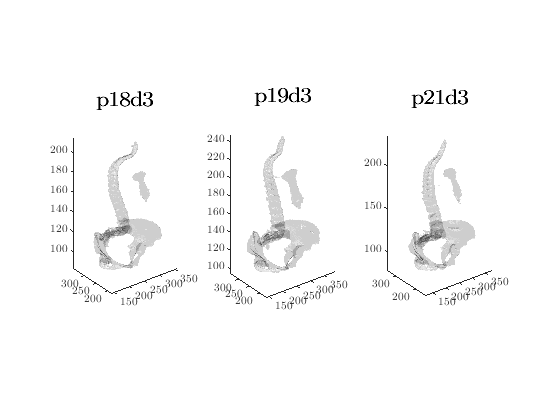

set(0,'DefaultTextFontname', 'LM Roman 9')
set(0,'DefaultAxesFontName', 'LM Roman 9')

pidxs = [18,3; 19,3; 21,3];

preds_path = "C:\.matlab_workspace\.data\ct_mask_preds\";
truth_path = "C:\.matlab_workspace\.data\ct_pt_volumes\";
figure();

pidx = pidxs(1,:);
spine1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "spine");
spine1 = spine1.spine;
spine1 = spine1 > 0.5;
stern1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "stern");
stern1 = stern1.stern;
stern1 = stern1 > 0.5;
pelvi1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "pelvi");
pelvi1 = pelvi1.pelvi;
pelvi1 = pelvi1 > 0.5;
pred_vol = spine1 + stern1 + pelvi1;
subplot(1,3,1);
fv = isosurface(pred_vol, .9);
p = patch(fv, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p.FaceAlpha = .1;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{16}p18d3")

pidx = pidxs(2,:);
spine1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "spine");
spine1 = spine1.spine;
spine1 = spine1 > 0.5;
stern1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "stern");
stern1 = stern1.stern;
stern1 = stern1 > 0.5;
pelvi1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "pelvi");
pelvi1 = pelvi1.pelvi;
pelvi1 = pelvi1 > 0.5;
pred_vol = spine1 + stern1 + pelvi1;
subplot(1,3,2);
fv = isosurface(pred_vol, .9);
p = patch(fv, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p.FaceAlpha = .1;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{16}p19d3")

pidx = pidxs(3,:);
spine1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "spine");
spine1 = spine1.spine;
spine1 = spine1 > 0.5;
stern1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "stern");
stern1 = stern1.stern;
stern1 = stern1 > 0.5;
pelvi1 = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "pelvi");
pelvi1 = pelvi1.pelvi;
pelvi1 = pelvi1 > 0.5;
pred_vol = spine1 + stern1 + pelvi1;
subplot(1,3,3);
fv = isosurface(pred_vol, .9);
p = patch(fv, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p.FaceAlpha = .1;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{16}p21d3")